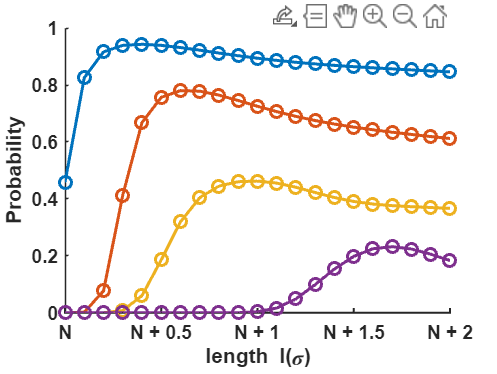

%考察在相同相互作用强度下锁死概率随聚合度N的变化
%作用强度e=4120, 采样次数count=10^7
clc;
clear all;

hold on
%加载三聚的概率数据
load("data_gausssampling_correlate_interlock3.mat")

X3=3:0.1:5;
P3=MC_result;
plot(X3,P3,'-o',LineWidth=1.5)
ylim([0 1])

%加载四聚的概率数据
load("data_gausssampling_correlate_interlock4.mat")
%横坐标固定为Nl~(N+1)l?
X4=3:0.1:5;
P4=MC_result;
plot(X4,P4,'-o',LineWidth=1.5)
ylim([0 1])

%加载五聚的概率数据
load("data_gausssampling_correlate_interlock5.mat")
%横坐标固定为Nl~(N+1)l?
X5=3:0.1:5;
P5=MC_result;
plot(X5,P5,'-o',LineWidth=1.5)
ylim([0 1])

%加载六聚的概率数据
load("data_gausssampling_correlate_interlock6.mat")
%横坐标固定为Nl~(N+1)l?
X6=3:0.1:5;
P6=MC_result;
plot(X6,P6,'-o',LineWidth=1.5)
ylim([0 1])


hold off

set(gca,'linewidth',1,'FontWeight','bold','FontName','arial');
xlabel('length l(\sigma)','FontName','arial','FontWeight','bold'); 
ylabel('Probability','FontName','arial','FontWeight','bold');

xticks([3 3.5 4 4.5 5])
xticklabels({'N','N + 0.5','N + 1','N + 1.5','N + 2'})